## `Question 01`

`Generate a binary sequence of length L = 1000, considering D 2 f0; 1g and Pr(D = 0) = Pr(D = 1) = 1/2: Use the binary sequence to generate a stream of rectangular pulses of amplitude S, where S belongs to +-A with A = 1.  `

% defining variables

L = 100000;  % binary sequence of length. This value should be change to 100 000 from question 5
A = 1;  % this value can be changed according to your need (such that A=1, A=2, A=3)
miu = 0;
sigma = 1;
tau = 0;

miu_i = 0;
sigma_i = 1;
alpha = 2;

% generating the random bit stream of length L

D = ones(1,L); % create an array of length of ones. dimension = 1 x L

rand = randperm(L, L/2); % generate random indexes with length of half of sequence length  within sequence.
D(rand) = zeros(1, L/2); % replace the D sequence with zeros for random indexes.

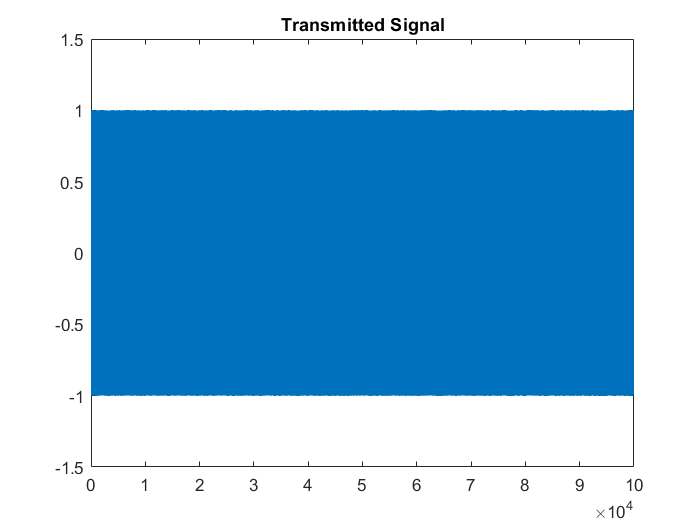

% generate a stream of rectangular pulses

Z = zeros(1, L); % generating a empty zero array as pulse

for index1 = 1:L
    if D(index1) == 1
        S(index1) = A;   % if bit is equal to one assign it as +1
    
    else
        S(index1) = -1 * A;   % if bit is equal to zero assign it as -1
    end
end

% plotting the transmitted signal 
figure;
stairs([1:L], S);
ylim([-1.5 1.5]);
title("Transmitted Signal")

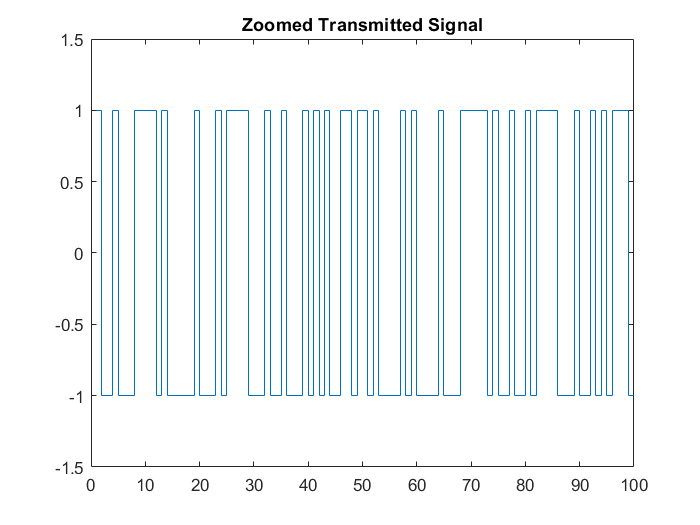


% Zoomed version of Tx Signal
figure;
stairs([1:L], S);
ylim([-1.5 1.5]);
xlim([0 100]);
title("Zoomed Transmitted Signal")

## `Question 02`

`Generate an AWGN sequence, also of length L = 1000, considering ``σ`

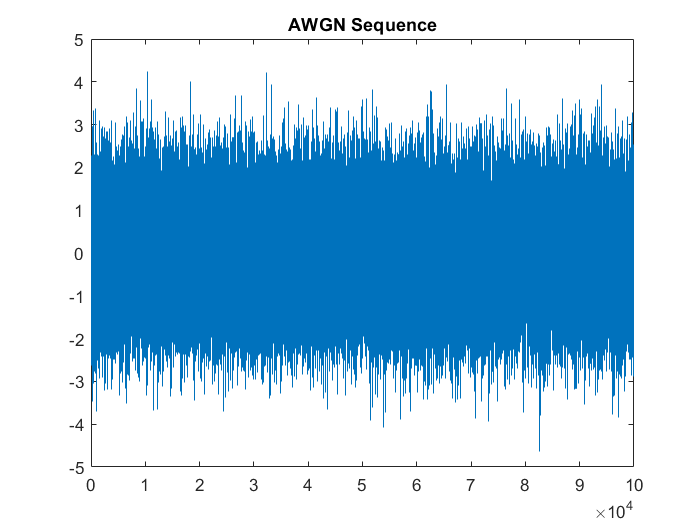

N = miu + sigma*randn(1,L); % generate normal distributed random numbers with mean (miu) and standard deviation (sigma)
figure;
stairs([1:L],N);
title("AWGN Sequence")

## `Question 03`

`Plot the sequence of ``R ``and observe the impact of the variance of noise on  R` `by varying ``σ``2 .`

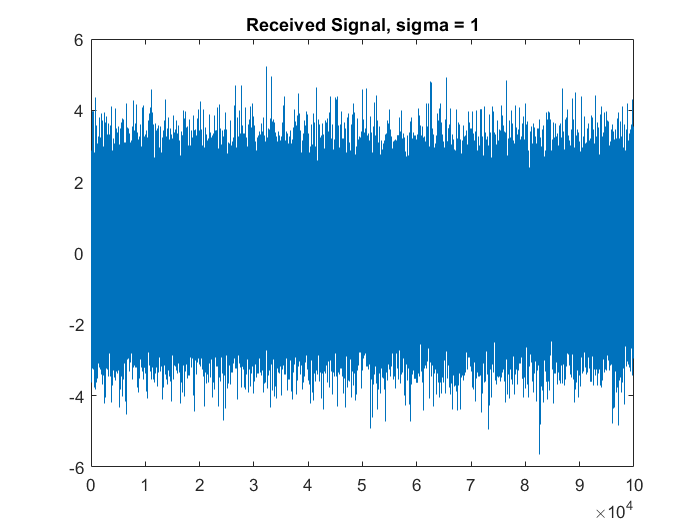

R = S + N; %  add AWGN to the Tx signal 

figure; % plot the Received signal
stairs([1:L],R);
title("Received Signal, sigma = 1")

## `Question 04`

`Sketch and compare the sequence of ``Y ``with the transmitted signal.  `

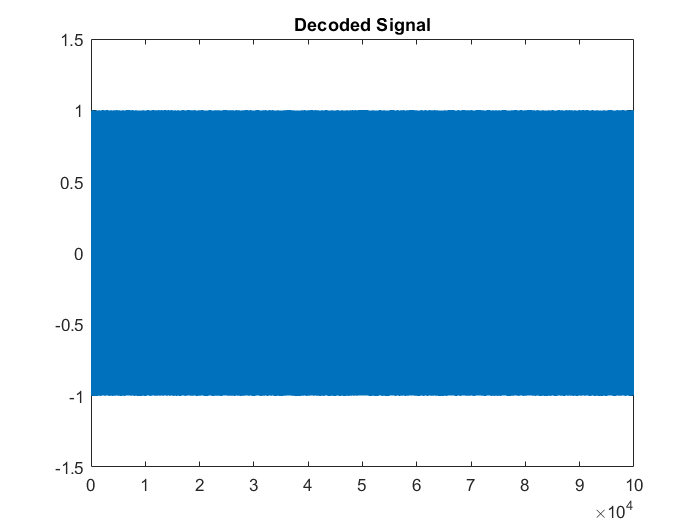

% generate a sequence of Y

Y = zeros(1, L); % generating a empty zero array

for index2 = 1:L
    if R(index2) > tau
        Y(index2) = A;   % if value is greater than threshold(tau) assign it as +1
    
    else
        Y(index2) = -1 * A;   % if value is less than or equal to threshold(tau) assign it as -1
    end
end

% plot the decoded signal
figure;
stairs([1:L], Y);
ylim([-1.5 1.5]);
title("Decoded Signal")

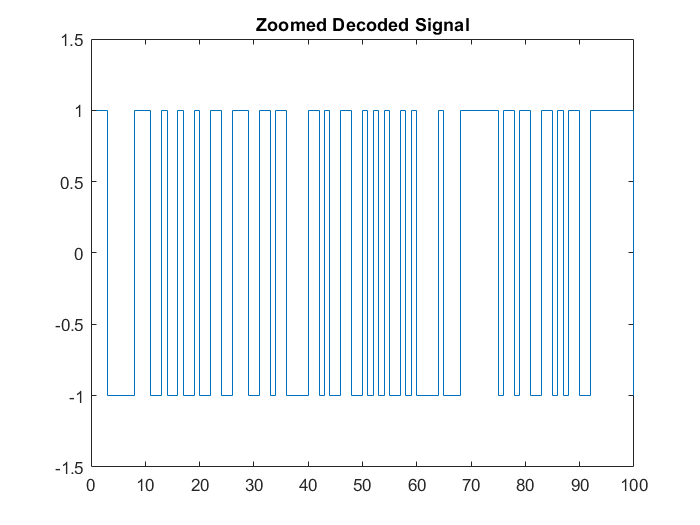


% plot the zoomed decoded signal
figure;
stairs([1:L], Y);
ylim([-1.5 1.5]);
xlim([0 100]);
title("Zoomed Decoded Signal")

## `Question 05`

`Repeat the above steps for a sequence of length ``L ``= 100``; ``000. Write a code to generate and plot the histogram of the received sequence taking the no of bins as 10. Compare your result with the one generated from the built-in function hist() of MATLAB. `

`    (a) Change the no of bins from 10 to 100 and observe the impact.   `

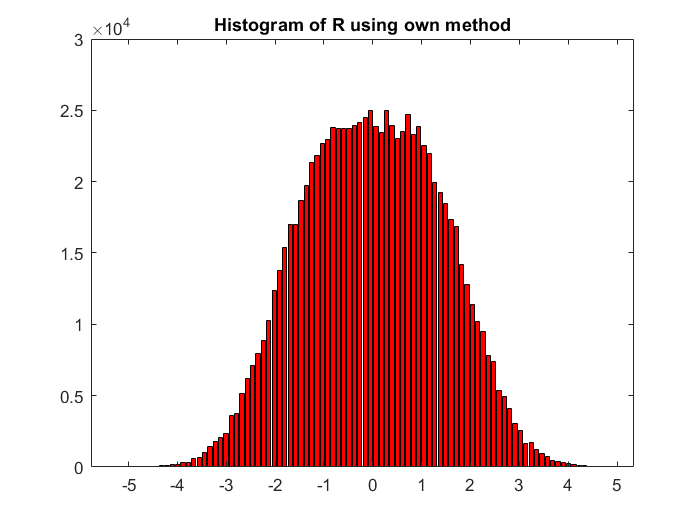


no_of_bins = 100; % this should be change to 100 for question 5(a) and for question 5 it should be equal to 10
mamimum_R = max(R); % determine the maximum amplitude value of received signal
minimum_R = min(R); % determine the minimum amplitude value of received signal
width = (mamimum_R-minimum_R)/(no_of_bins-1);  % determine the width of interval
center_of_interval = [minimum_R:width:mamimum_R]; % array of bin intervals


values_for_interval = zeros(1,no_of_bins); 
for index3 = 1:L
    for index4 = 1:no_of_bins
        if (R(index3) >= center_of_interval(index4) - width/2) && (R(index3) < center_of_interval(index4) + width/2) % check values within given interval
            values_for_interval(index4) = values_for_interval(index4) + 1; % add the count of availability within the interval
        end
    end
end

hist_vals = values_for_interval / width; % normalized the values

%plot the histogram
figure;
bar_graph1 = bar(center_of_interval,hist_vals);
set(bar_graph1,'FaceColor','red');
title("Histogram of R using own method");

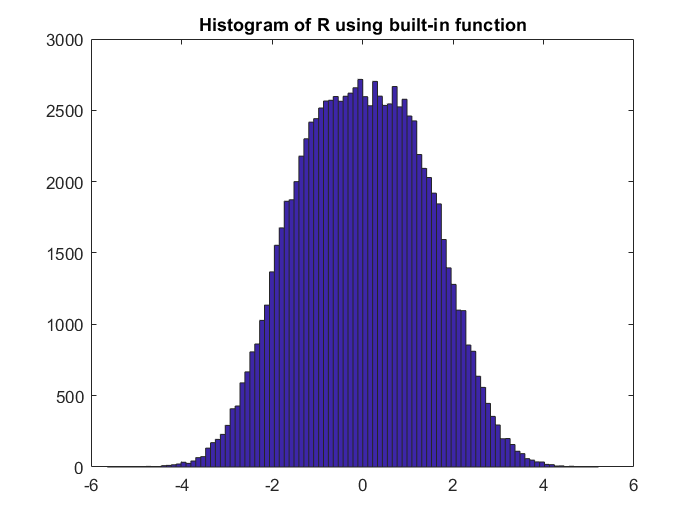

% plotting histogram using hist() built-in function
figure;
hist(R,no_of_bins);
title("Histogram of R using built-in function");

`keep no of bins as 100 for further calculations.`

## `Question 05`

`    (b) pdf of f_R|S(r|S=A) & histogram`

% determine the sequence for conditional pdf of f_R|S(r|S=A)

f_rS_One = []; % create a sequence for conditional pdf
i_1 = 1;

% fill the above array with Received signal values when Transmitted signal value equals to A (=1)
for index5 = 1:L 
    if S(index5) == A
        f_rS_One(i_1) = R(index5);
        i_1 = i_1 + 1;
    end
end

[counts1,centers1] = hist(f_rS_One, no_of_bins); % find histograms and centers for each interval

counts1 = counts1 / (length(f_rS_One)*width) % normalize over distribution

counts1 =     0.0002         0    0.0004         0    0.0005    0.0004    0.0002    0.0007    0.0007    0.0015    0.0016    0.0018    0.0031    0.0044    0.0044    0.0047    0.0071    0.0106    0.0080    0.0140    0.0193    0.0228    0.0292    0.0343    0.0381    0.0458    0.0493    0.0607    0.0713    0.0843    0.0930    0.0960    0.1127    0.1228    0.1468    0.1618    0.1808    0.1965    0.1990    0.2142    0.2359    0.2517    0.2565    0.2558    0.2733    0.2995    0.3028    0.3037    0.3136    0.3012


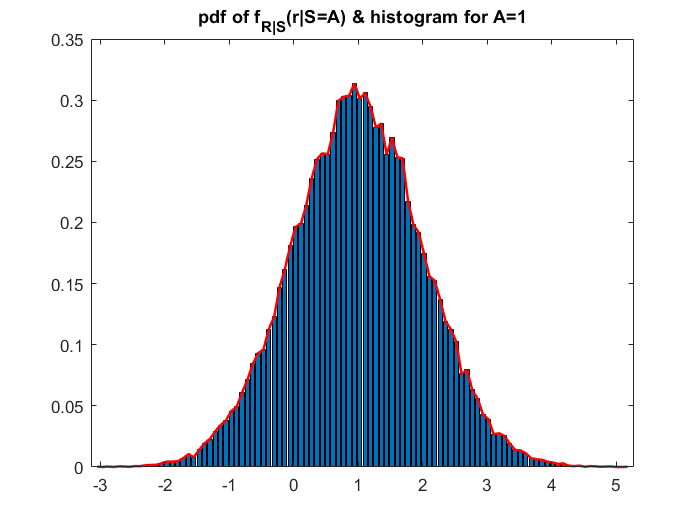


% plot the histogram and pdf on same figure
figure;
bar(centers1, counts1);
hold on;
figure2 = plot(centers1, counts1, 'r'); % plot the pdf
set(figure2,'linewidth',1.5);
title("pdf of f_{R|S}(r|S=A) & histogram for A=1");

% determine the sequence for conditional pdf of f_R|S(r|S=-A)

f_rS_minusOne = []; % create a sequence for conditional pdf
i_2 = 1;

% fill the above array with Received signal values when Transmitted signal value equals to -A (= -1)
for index6 = 1:L 
    if S(index6) == -1 * A
        f_rS_minusOne(i_2) = R(index6);
        i_2 = i_2 + 1;
    end
end

[counts2,centers2] = hist(f_rS_minusOne, no_of_bins); % find histograms and centers for each interval

counts2 = counts2 / (length(f_rS_minusOne)*width) % normalize over distribution

counts2 =     0.0002         0         0         0         0         0         0    0.0002    0.0004    0.0004    0.0005    0.0002    0.0002    0.0011    0.0016    0.0016    0.0022    0.0036    0.0031    0.0046    0.0047    0.0064    0.0097    0.0104    0.0168    0.0219    0.0244    0.0290    0.0348    0.0376    0.0511    0.0617    0.0666    0.0843    0.1016    0.1051    0.1268    0.1286    0.1532    0.1633    0.1908    0.2087    0.2339    0.2475    0.2693    0.2672    0.2791    0.2910    0.3072    0.3178


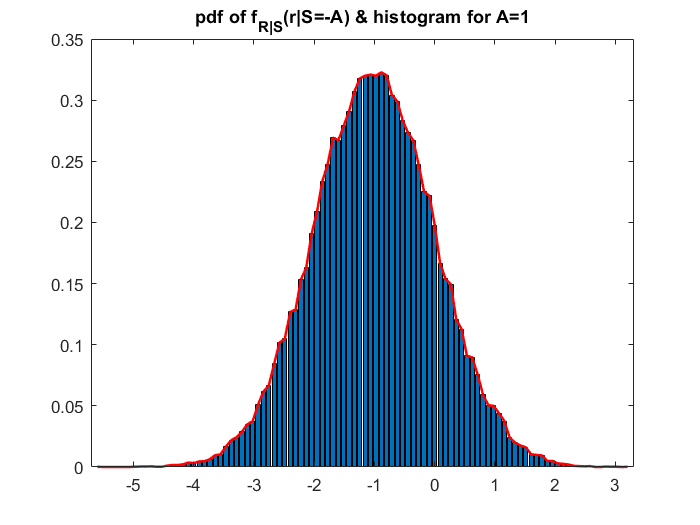


% plot the histogram and pdf on same figure
figure;
bar(centers2, counts2);
hold on;
figure2 = plot(centers2, counts2, 'r'); % plot the pdf
set(figure2,'linewidth',1.5);
title("pdf of f_{R|S}(r|S=-A) & histogram for A=1");

## `Question 05`

`    (c) Find E[R|S = A] ; E[R|S = -A] and E[R]  `

% determine E[R|S = A] using previously calculated PDFs

E_RS_A = 0; % initialize the value

for index7 = 1:no_of_bins
    E_RS_A = (centers1.*counts1)*width;  % finge the summation according to the definition of conditional expected value
end

val_E_RS_A = sum(E_RS_A);
val_E_RS_A

val_E_RS_A = 0.9933

% determine E[R|S = -A] using previously calculated PDFs

E_RS_minusA = 0; % initialize the value

for index7 = 1:no_of_bins
    E_RS_minusA = (centers2.*counts2)*width;  % finge the summation according to the definition of conditional expected value
end

val_E_RS_minusA = sum(E_RS_minusA);
val_E_RS_minusA

val_E_RS_minusA = -1.0007

% DEtermine E[R} using previously calculated PDFs

[counts3,centers3] = hist(R, no_of_bins); % find histograms and centers for each interval
counts3 = counts3 / (length(R)*width) % normalize over distribution

counts3 =     0.0001         0         0         0         0         0    0.0002    0.0002    0.0004    0.0001    0.0002    0.0009    0.0010    0.0015    0.0019    0.0030    0.0023    0.0038    0.0060    0.0067    0.0120    0.0156    0.0177    0.0209    0.0266    0.0372    0.0390    0.0538    0.0608    0.0736    0.0786    0.0938    0.1035    0.1248    0.1417    0.1529    0.1699    0.1708    0.1824    0.1987    0.2099    0.2205    0.2227    0.2295    0.2340    0.2345    0.2369    0.2339    0.2371    0.2391



E_R = 0; % initialize the value

for index8 = 1:no_of_bins
    E_R = (centers3.*counts3)*width;  % finge the summation according to the definition of expected value
end

val_E_R = sum(E_R);
val_E_R

val_E_R = -0.0038

## `Question 05`

`    (d) Similarly, sketch the PDF f_R(r).`  

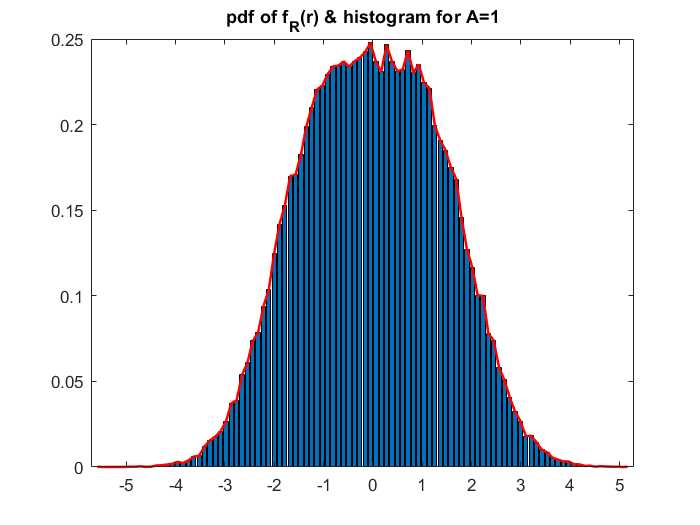

% plot the histogram and pdf on same figure
figure;
bar(centers3, counts3);
hold on;
figure3 = plot(centers3, counts3, 'r'); % plot the pdf
set(figure3,'linewidth',1.5);
title("pdf of f_{R}(r) & histogram for A=1");

## `Question 06`

`Now, consider that there is interference I from other transmitters in addition to noise. Thus, the received sample can then be written as R = S + N + I:`

`Assuming that I is also Gaussian distributed with zero mean and variance σ2i = 1, repeat step 5 - (b) to (d) and discuss the impact of the addition of interference.`

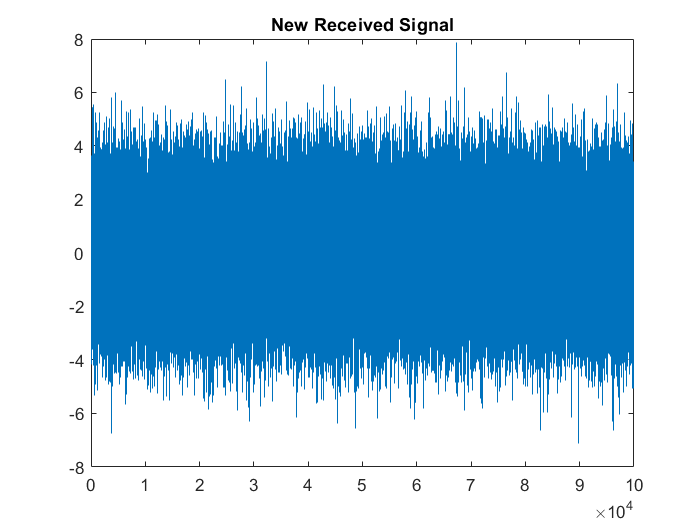

% generating new received signal as follows

I = miu_i + sigma_i*randn(1,L); % generate normal distributed random numbers with mean (miu_i) and standard deviation (sigma_i) for interference
R_N1 = S + N + I; % generation of received signal with noise and interference

figure; % plot the Received signal
stairs([1:L],R_N1);
title("New Received Signal");

`Repeat step 5 - (b) to (d)  `

% ----------------------part b--------------------------------------------------

% determine the sequence for conditional pdf of f_R|S(r|S=A)

f_rS_One_N1 = []; % create a sequence for conditional pdf
i_1_N1 = 1;

% fill the above array with Received signal values when Transmitted signal value equals to A (=1)
for index5_N1 = 1:L 
    if S(index5_N1) == A
        f_rS_One_N1(i_1_N1) = R_N1(index5_N1);
        i_1_N1 = i_1_N1 + 1;
    end
end

[counts1_N1,centers1_N1] = hist(f_rS_One_N1, no_of_bins); % find histograms and centers for each interval

counts1_N1 = counts1_N1 / (length(f_rS_One_N1)*width) % normalize over distribution

counts1_N1 =     0.0002    0.0005    0.0002    0.0002    0.0005    0.0002    0.0002    0.0004    0.0009    0.0007    0.0022    0.0040    0.0026    0.0044    0.0069    0.0060    0.0089    0.0120    0.0139    0.0232    0.0257    0.0332    0.0403    0.0494    0.0511    0.0637    0.0713    0.0866    0.1023    0.1140    0.1259    0.1478    0.1707    0.1775    0.1994    0.2240    0.2309    0.2390    0.2782    0.2800    0.2942    0.3004    0.3105    0.3165    0.3251    0.3181    0.3147    0.3170    0.3243    0.3025


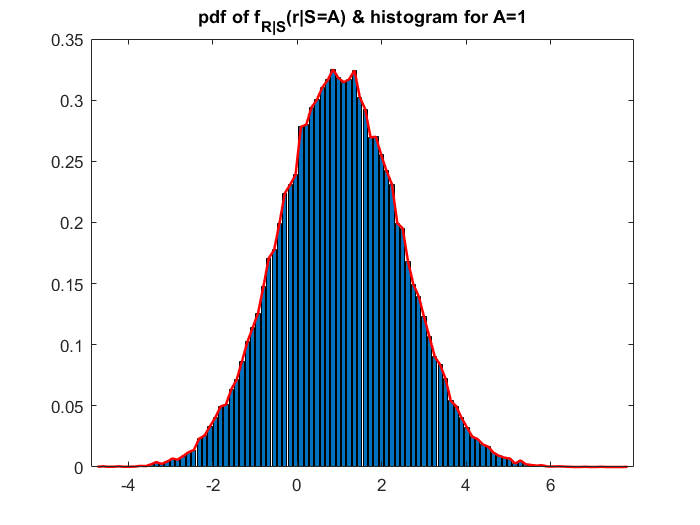


% plot the histogram and pdf on same figure
figure;
bar(centers1_N1, counts1_N1);
hold on;
figure2_N1 = plot(centers1_N1, counts1_N1, 'r'); % plot the pdf
set(figure2_N1,'linewidth',1.5);
title("pdf of f_{R|S}(r|S=A) & histogram for A=1");


% determine the sequence for conditional pdf of f_R|S(r|S=-A)

f_rS_minusOne_N2 = []; % create a sequence for conditional pdf
i_2_N2 = 1;

% fill the above array with Received signal values when Transmitted signal value equals to -A (= -1)
for index6_N2 = 1:L 
    if S(index6_N2) == -1 * A
        f_rS_minusOne_N2(i_2_N2) = R_N1(index6_N2);
        i_2_N2 = i_2_N2 + 1;
    end
end

[counts2_N2,centers2_N2] = hist(f_rS_minusOne_N2, no_of_bins); % find histograms and centers for each interval

counts2_N2 = counts2_N2 / (length(f_rS_minusOne_N2)*width) % normalize over distribution

counts2_N2 =     0.0002         0         0    0.0005    0.0002         0    0.0005    0.0004    0.0005    0.0004    0.0011    0.0005    0.0016    0.0016    0.0024    0.0033    0.0033    0.0051    0.0053    0.0077    0.0104    0.0113    0.0133    0.0202    0.0250    0.0288    0.0332    0.0376    0.0498    0.0545    0.0589    0.0766    0.0854    0.0932    0.1085    0.1204    0.1324    0.1428    0.1574    0.1748    0.2039    0.2049    0.2184    0.2421    0.2413    0.2594    0.2716    0.2886    0.2968    0.3123


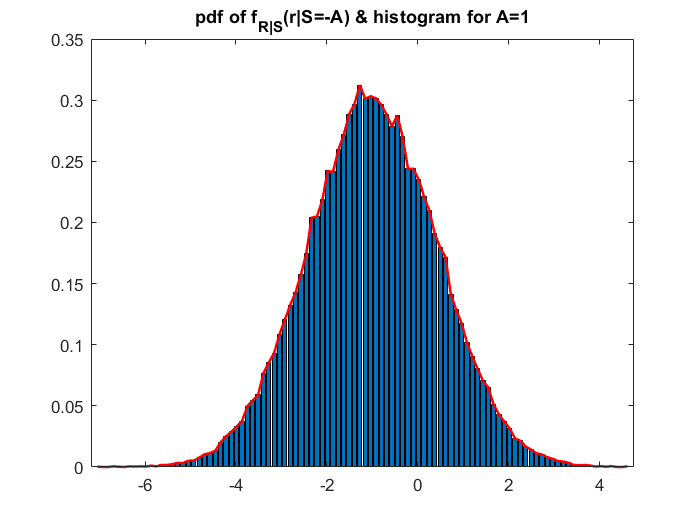



% plot the histogram and pdf on same figure
figure;
bar(centers2_N2, counts2_N2);
hold on;
figure2_N2 = plot(centers2_N2, counts2_N2, 'r'); % plot the pdf
set(figure2_N2,'linewidth',1.5);
title("pdf of f_{R|S}(r|S=-A) & histogram for A=1");




% ------------------------ part c -------------------------------

% determine E[R|S = A] using previously calculated PDFs

E_RS_A_n1 = 0; % initialize the value

for index7_n1 = 1:no_of_bins
    E_RS_A_n1 = (centers1_N1.*counts1_N1)*width;  % finge the summation according to the definition of conditional expected value
end

val_E_RS_A_n1 = sum(E_RS_A_n1);
val_E_RS_A_n1

val_E_RS_A_n1 = 1.0028



% determine E[R|S = -A] using previously calculated PDFs

E_RS_minusA_n2 = 0; % initialize the value

for index7_n2 = 1:no_of_bins
    E_RS_minusA_n2 = (centers2_N2.*counts2_N2)*width;  % finge the summation according to the definition of conditional expected value
end

val_E_RS_minusA_n2 = sum(E_RS_minusA_n2);
val_E_RS_minusA_n2

val_E_RS_minusA_n2 = -0.9967



% DEtermine E[R} using previously calculated PDFs

[counts3_n,centers3_n] = hist(R_N1, no_of_bins); % find histograms and centers for each interval
counts3_n = counts3_n / (length(R_N1)*width) % normalize over distribution

counts3_n =     0.0001         0    0.0001    0.0003    0.0001    0.0003    0.0003    0.0003    0.0006    0.0005    0.0013    0.0016    0.0024    0.0025    0.0035    0.0049    0.0080    0.0080    0.0134    0.0164    0.0197    0.0244    0.0340    0.0347    0.0485    0.0541    0.0656    0.0741    0.0869    0.0969    0.1117    0.1355    0.1435    0.1605    0.1796    0.1893    0.2074    0.2228    0.2454    0.2542    0.2589    0.2732    0.2769    0.2837    0.2964    0.2941    0.2928    0.3048    0.3047    0.2965




E_R_n = 0; % initialize the value

for index8_n = 1:no_of_bins
    E_R_n = (centers3_n.*counts3_n)*width;  % finge the summation according to the definition of expected value
end

val_E_R_n = sum(E_R_n);
val_E_R_n

val_E_R_n = 0.0032

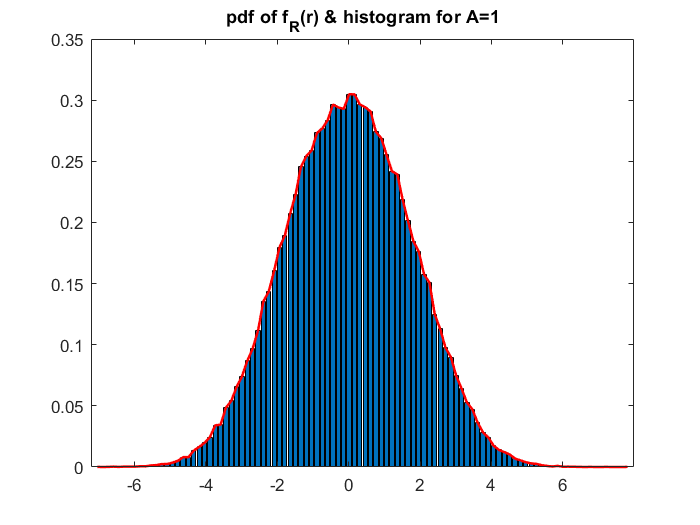


% -----------------------part d--------------------------------------------------

% plot the histogram and pdf on same figure
figure;
bar(centers3_n, counts3_n);
hold on;
figure3_n = plot(centers3_n, counts3_n, 'r'); % plot the pdf
set(figure3_n,'linewidth',1.5);
title("pdf of f_{R}(r) & histogram for A=1");

## `Question 07`

`Finally, consider that the received signal is amplified by a factor of α, such that R = αS + N:`

`Repeat step 5 - (b) to (d) and discuss the impact of scaling.  `

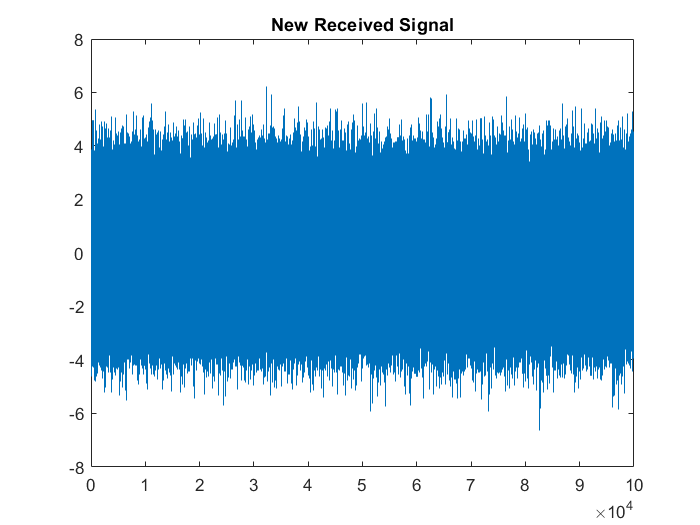

R_N2 = alpha*S + N;  % new received signal

figure; % plot the Received signal
stairs([1:L],R_N2);
title("New Received Signal");


% ----------------------part b--------------------------------------------------

% determine the sequence for conditional pdf of f_R|S(r|S=A)

f_rS_One_M1 = []; % create a sequence for conditional pdf
i_1_M1 = 1;

% fill the above array with Received signal values when Transmitted signal value equals to A (=1)
for index5_M1 = 1:L 
    if S(index5_M1) == A
        f_rS_One_M1(i_1_M1) = R_N2(index5_M1);
        i_1_M1 = i_1_M1 + 1;
    end
end

[counts1_M1,centers1_M1] = hist(f_rS_One_M1, no_of_bins); % find histograms and centers for each interval

counts1_M1 = counts1_M1 / (length(f_rS_One_M1)*width) % normalize over distribution

counts1_M1 =     0.0002         0    0.0004         0    0.0005    0.0004    0.0002    0.0007    0.0007    0.0015    0.0016    0.0018    0.0031    0.0044    0.0044    0.0047    0.0071    0.0106    0.0080    0.0140    0.0193    0.0228    0.0292    0.0343    0.0381    0.0458    0.0493    0.0607    0.0713    0.0843    0.0930    0.0960    0.1127    0.1228    0.1468    0.1618    0.1808    0.1965    0.1990    0.2142    0.2359    0.2517    0.2565    0.2558    0.2733    0.2995    0.3028    0.3037    0.3136    0.3012


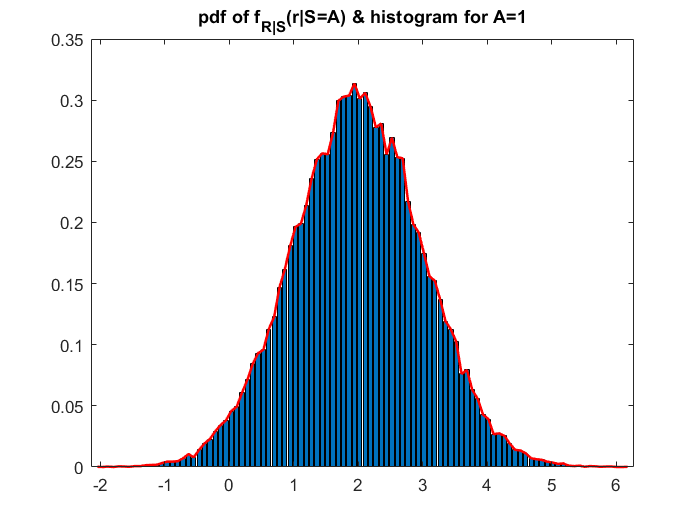


% plot the histogram and pdf on same figure
figure;
bar(centers1_M1, counts1_M1);
hold on;
figure2_M1 = plot(centers1_M1, counts1_M1, 'r'); % plot the pdf
set(figure2_M1,'linewidth',1.5);
title("pdf of f_{R|S}(r|S=A) & histogram for A=1");


% determine the sequence for conditional pdf of f_R|S(r|S=-A)

f_rS_minusOne_M2 = []; % create a sequence for conditional pdf
i_2_M2 = 1;

% fill the above array with Received signal values when Transmitted signal value equals to -A (= -1)
for index6_M2 = 1:L 
    if S(index6_M2) == -1 * A
        f_rS_minusOne_M2(i_2_M2) = R_N2(index6_M2);
        i_2_M2 = i_2_M2 + 1;
    end
end

[counts2_M2,centers2_M2] = hist(f_rS_minusOne_M2, no_of_bins); % find histograms and centers for each interval

counts2_M2 = counts2_M2 / (length(f_rS_minusOne_M2)*width) % normalize over distribution

counts2_M2 =     0.0002         0         0         0         0         0         0    0.0002    0.0004    0.0004    0.0005    0.0002    0.0002    0.0011    0.0016    0.0016    0.0022    0.0036    0.0031    0.0046    0.0047    0.0064    0.0097    0.0104    0.0168    0.0219    0.0244    0.0290    0.0348    0.0376    0.0511    0.0617    0.0666    0.0843    0.1016    0.1051    0.1268    0.1286    0.1532    0.1633    0.1908    0.2087    0.2339    0.2475    0.2693    0.2672    0.2791    0.2910    0.3072    0.3178


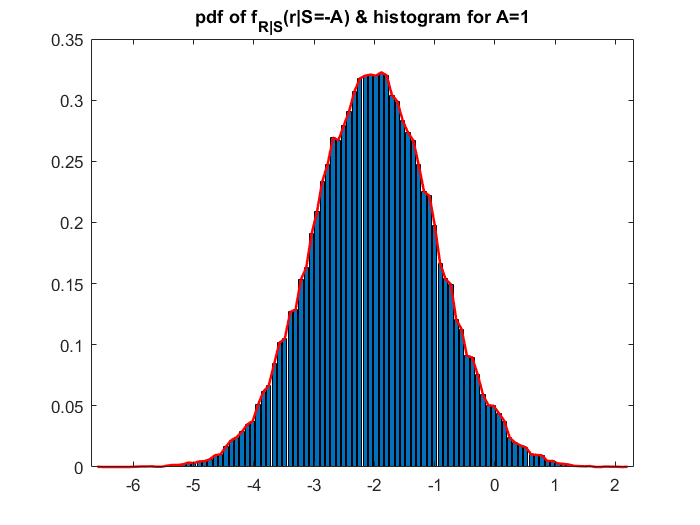



% plot the histogram and pdf on same figure
figure;
bar(centers2_M2, counts2_M2);
hold on;
figure2_M2 = plot(centers2_M2, counts2_M2, 'r'); % plot the pdf
set(figure2_M2,'linewidth',1.5);
title("pdf of f_{R|S}(r|S=-A) & histogram for A=1");




% ------------------------ part c -------------------------------

% determine E[R|S = A] using previously calculated PDFs

E_RS_A_m1 = 0; % initialize the value

for index7_m1 = 1:no_of_bins
    E_RS_A_m1 = (centers1_M1.*counts1_M1)*width;  % finge the summation according to the definition of conditional expected value
end

val_E_RS_A_m1 = sum(E_RS_A_m1);
val_E_RS_A_m1

val_E_RS_A_m1 = 1.9933



% determine E[R|S = -A] using previously calculated PDFs

E_RS_minusA_m2 = 0; % initialize the value

for index7_m2 = 1:no_of_bins
    E_RS_minusA_m2 = (centers2_M2.*counts2_M2)*width;  % finge the summation according to the definition of conditional expected value
end

val_E_RS_minusA_m2 = sum(E_RS_minusA_m2);
val_E_RS_minusA_m2

val_E_RS_minusA_m2 = -2.0007



% DEtermine E[R} using previously calculated PDFs

[counts3_m,centers3_m] = hist(R_N2, no_of_bins); % find histograms and centers for each interval
counts3_m = counts3_m / (length(R_N2)*width) % normalize over distribution

counts3_m =     0.0001         0         0         0         0    0.0002    0.0003    0.0004    0.0001    0.0009    0.0012    0.0017    0.0024    0.0031    0.0042    0.0066    0.0090    0.0153    0.0186    0.0235    0.0286    0.0438    0.0476    0.0663    0.0808    0.0925    0.1050    0.1223    0.1502    0.1711    0.1874    0.1935    0.2070    0.2215    0.2307    0.2320    0.2346    0.2313    0.2189    0.2105    0.1977    0.1872    0.1651    0.1546    0.1310    0.1159    0.0972    0.0856    0.0784    0.0732




E_R_m = 0; % initialize the value

for index8_m = 1:no_of_bins
    E_R_m = (centers3_m.*counts3_m)*width;  % finge the summation according to the definition of expected value
end

val_E_R_m = sum(E_R_m);
val_E_R_m

val_E_R_m = -0.0037

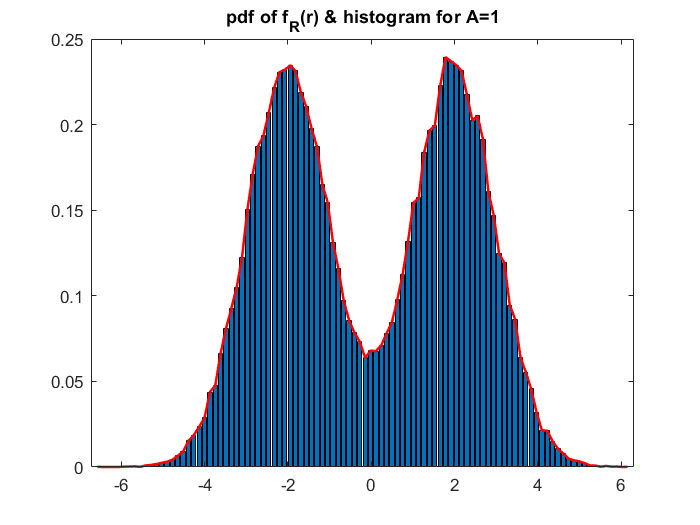


% -----------------------part d--------------------------------------------------

% plot the histogram and pdf on same figure
figure;
bar(centers3_m, counts3_m);
hold on;
figure3_m = plot(centers3_m, counts3_m, 'r'); % plot the pdf
set(figure3_m,'linewidth',1.5);
title("pdf of f_{R}(r) & histogram for A=1");